clear all

temp = readtable('data.csv') % This is table

temp = 519×2 table
      Var1        Var2 
    _________    ______

            0         0
    0.0041667         0
    0.0083333         0
       0.0125         0
     0.016667         0
     0.020833         0
        0.025         0
     0.029167         0
     0.033333         0
       0.0375         0
     0.041667         0
     0.045833         0
         0.05         0
     0.054167         0
     0.058333    -0.002
       0.0625    -0.002


data = table2array(temp) % convert table to array

data =          0         0
    0.0042         0
    0.0083         0
    0.0125         0
    0.0167         0
    0.0208         0
    0.0250         0
    0.0292         0
    0.0333         0
    0.0375         0


%data=[t,y] %first column is time, second column is y displacement in meters
t=data(:,1) % time

t =          0
    0.0042
    0.0083
    0.0125
    0.0167
    0.0208
    0.0250
    0.0292
    0.0333
    0.0375


y=data(:,2) % displacement

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


dt=t(2)-t(1)

dt = 0.0042


% Numerični odvod
% doc diff
% Y = [X(2)-X(1) X(3)-X(2) ... X(m)-X(m-1)]
vy=diff(y)/dt % velocity

vy =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


ay=diff(vy)/dt % acceleration

ay =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## no smoothing

close all
figure
plot(t,y,'k',LineWidth=2)
clear ax
ax=gca

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-0.3000 0.4000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-0.3000 0.4000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-0.3000 0.4000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


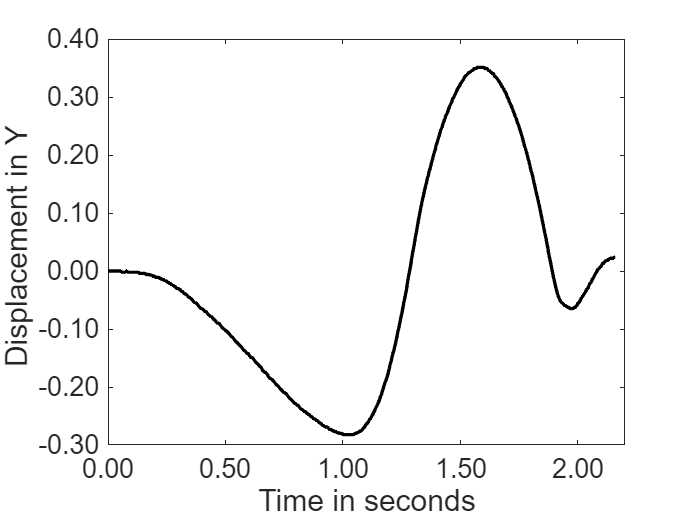

xlim([0 2.2])
ylabel('Displacement in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'displacement_NOsmooth.png')


figure
plot(t(1:end-1),vy,'b',LineWidth=2)
clear ax
ax=gca

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-3 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-3 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-3 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


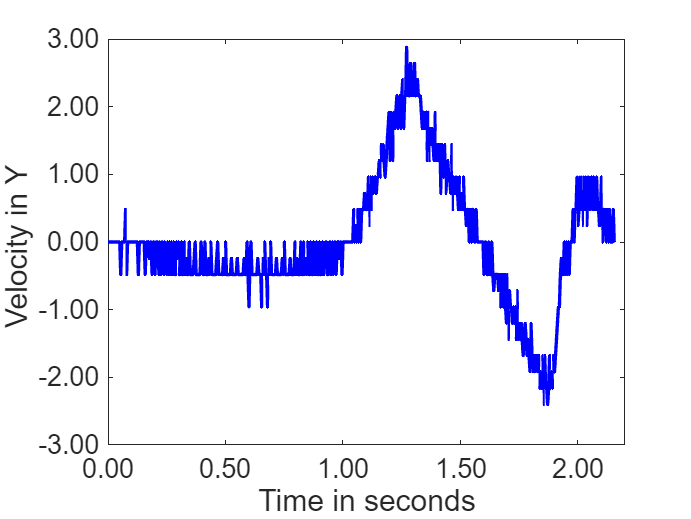

xlim([0 2.2])
ylabel('Velocity in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'velocity_NOsmooth.png')


figure
plot(t(1:end-2),ay,'r',LineWidth=2)
clear ax
ax=gca

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-250 200]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ytickformat('%.0f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-300 200]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-300 200]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


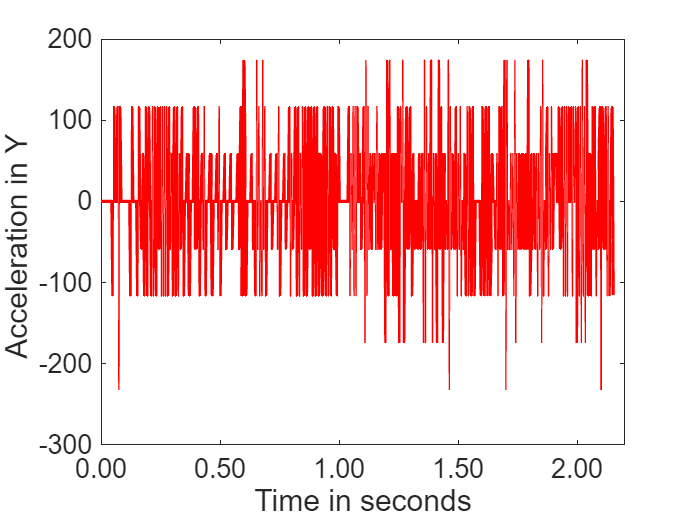

xlim([0 2.2])
ylabel('Acceleration in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'acceleration_NOsmooth.png')

## SMOOTH %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% ys=smooth(y,30,'sgolay') % smooth displacement
% vys=diff(ys)/dt % calculate velocity from smoothed data
% vys=smooth(vys,30,'sgolay') % smooth it again or not ??????
% ays=diff(vys)/dt

## more user friendly

mywindow=30 % 5 15 30

mywindow = 30

setmethod='moving' % 'moving' 'lowess' 'loess' 'sgolay' 'rlowess' 'rloess'

setmethod = 'moving'

ys=smooth(y,mywindow,setmethod) % smooth displacement

ys =          0
         0
         0
         0
         0
         0
         0
   -0.0001
   -0.0004
   -0.0005


vys=diff(ys)/dt % calculate velocity from smoothed data

vys =          0
         0
         0
         0
         0
         0
   -0.0320
   -0.0527
   -0.0416
   -0.0108


vys=smooth(vys,mywindow,setmethod) % smooth it again or not ??????

vys =          0
         0
         0
   -0.0046
   -0.0140
   -0.0152
   -0.0164
   -0.0166
   -0.0166
   -0.0183


ays=diff(vys)/dt % acceleration

ays =          0
         0
   -1.0971
   -2.2713
   -0.2743
   -0.2958
   -0.0340
         0
   -0.4181
   -0.3385


%%%%

close all
figure
plot(t,ys,'k',LineWidth=2)
clear ax
ax=gca

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-0.3000 0.4000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-0.3000 0.4000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-0.3000 0.4000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


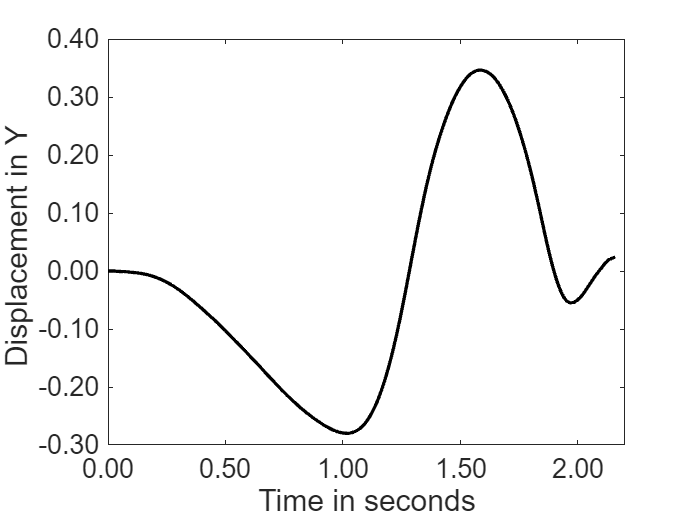

xlim([0 2.2])
ylabel('Displacement in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'displacement_smooth.png')


figure
plot(t(1:end-1),vys,'b',LineWidth=2)
clear ax
ax=gca

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-2 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-2 2.0264]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-2 2.0264]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


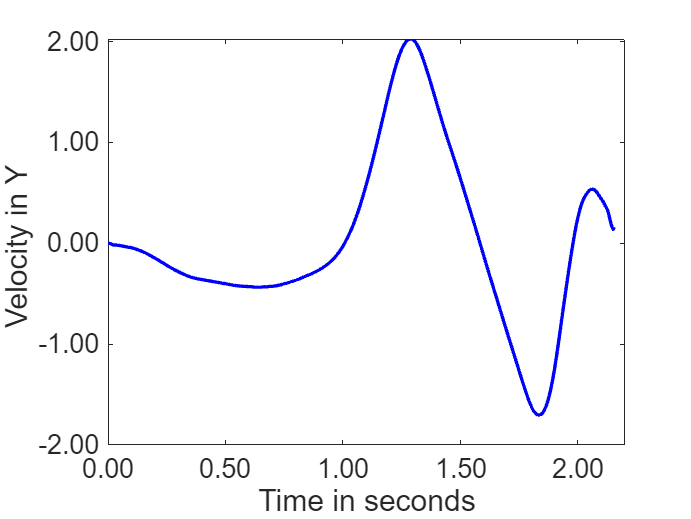

xlim([0 2.2])
ylabel('Velocity in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'velocity_smooth.png')


figure
plot(t(1:end-2),ays,'r',LineWidth=2)
clear ax
ax=gca

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-15 20]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ytickformat('%.0f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-15 20]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-15 20]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


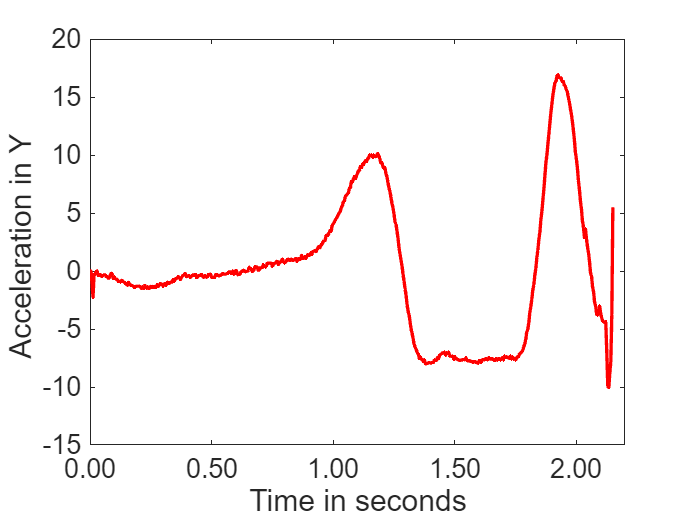

xlim([0 2.2])
ylabel('Acceleration in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'acceleration_smooth.png')

## weighted smooth user defined function

1 2 5 2 1 MYsmoothFUN

ys=MYsmoothFIBO(y) % smoothing

ys =    NaN
   NaN
     0
     0
     0
     0
     0
     0
     0
     0


vys=diff(ys)/dt % calculate velocity from smoothed data

vys =    NaN
   NaN
     0
     0
     0
     0
     0
     0
     0
     0


vys=MYsmoothFIBO(vys) % smooth it again or not ??????

vys =        NaN
       NaN
       NaN
       NaN
         0
         0
         0
         0
         0
   -0.0040


ays=diff(vys)/dt % acceleration

ays =        NaN
       NaN
       NaN
       NaN
         0
         0
         0
         0
   -0.9521
   -2.8562



close all
figure
plot(t,ys,'k',LineWidth=2)
clear ax
ax=gca

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-0.3000 0.4000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-0.3000 0.4000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-0.3000 0.4000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


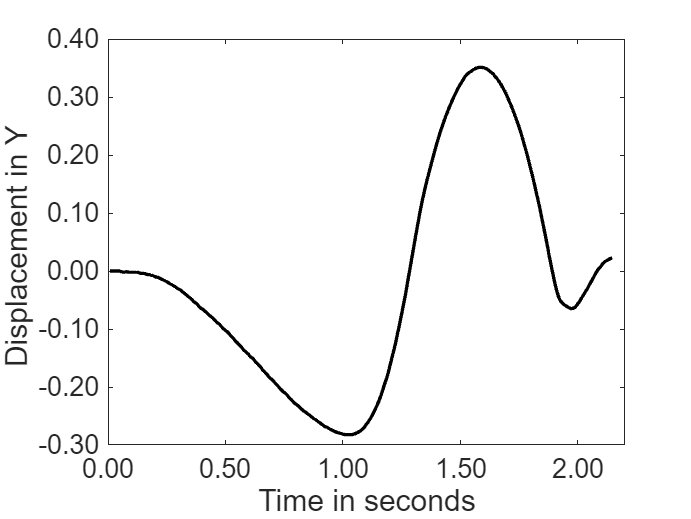

xlim([0 2.2])
ylabel('Displacement in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'displacement_smooth_USERfunc.png')


figure
plot(t(1:end-1),vys,'b',LineWidth=2)
clear ax
ax=gca

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-3 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-3 3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


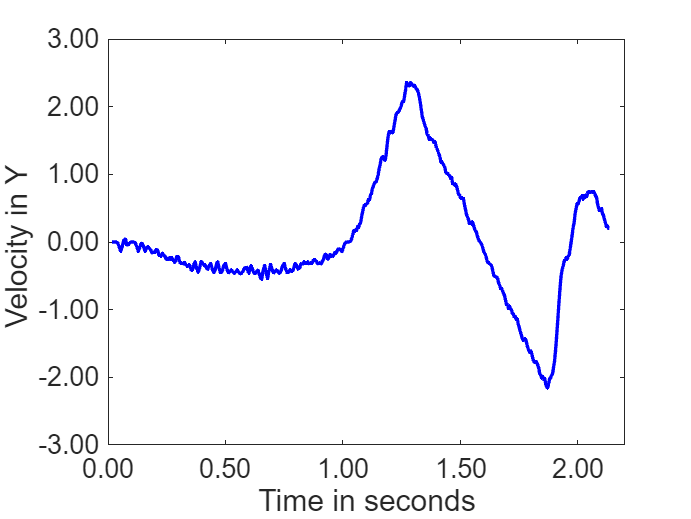

xlim([0 2.2])
ylabel('Velocity in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'velocity_smooth_USERfunc.png')


figure
plot(t(1:end-2),ays,'r',LineWidth=2)
clear ax
ax=gca

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-30 60]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ytickformat('%.0f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-40 60]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 16

ax =   Axes with properties:

             XLim: [0 2.5000]
             YLim: [-40 60]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


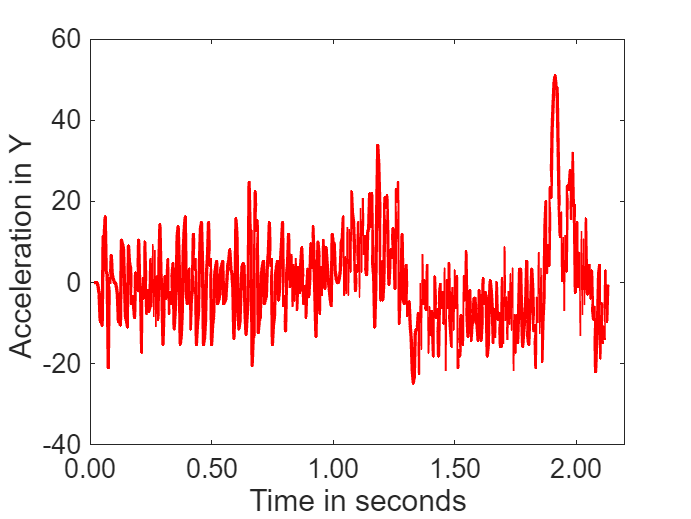

xlim([0 2.2])
ylabel('Acceleration in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'acceleration_smooth_USERfunc.png')


% For HW - demonstrate
% Fibonacci
% Matlab functions: fibonacci, flip, flipud, fliplr

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%% NOT for students %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% weighted smooth user defined function (LOG) FIBONACCI
win=31

win = 31

ys=MYsmoothFIBO(y,win) % window size is the input !!!!!

Error using MYsmoothFIBO
Too many input arguments.

vys=diff(ys)/dt % calculate velocity from smoothed data
vys=MYsmoothFIBO(vys,win) % smooth it again or not ??????
ays=diff(vys)/dt

close all
figur
e
plot(t,ys,'k',LineWidth=2)
clear ax
ax=gca
ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16
ax.YAxis.FontSize = 16
xlim([0 2.2])
ylabel('Displacement in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'displacement_smooth_USERfuncFIBO.png')

figure
plot(t(1:end-1),vys,'b',LineWidth=2)
clear ax
ax=gca
ytickformat('%.2f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16
ax.YAxis.FontSize = 16
xlim([0 2.2])
ylabel('Velocity in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'velocity_smooth_USERfuncFIBO.png')

figure
plot(t(1:end-2),ays,'r',LineWidth=2)
clear ax
ax=gca
ytickformat('%.0f')
xtickformat('%.2f')
ax.XAxis.FontSize = 16
ax.YAxis.FontSize = 16
xlim([0 2.2])
ylabel('Acceleration in Y ','FontSize',18)
xlabel('Time in seconds','FontSize',18)
saveas(gcf,'acceleration_smooth_USERfuncFIBO.png')